clear
close 
clc

load('SensorLog#3.mat');
LAT = Position.latitude;
LON = Position.longitude;
TIMEposition=Position.Timestamp;
Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
TIMEacc=Acceleration.Timestamp;

%% VARIABLES
step = 0.6; %m
totaldis = 0;
weight = 80;

for i = 1:(length(LAT)-1)       % Loop through every data sample
 LAT1 = LAT(i);                 % Latitude of the iLth sample
 LON1 = LON(i);                 % Longitude of the iOth sample
 LAT2 = LAT(i+1);               % Latitude of the (i+1)Ath sample
 LON2 = LON(i+1);               % Latitude of the (i+1)Lth sample
 tx = txsite('Name','MathWorks','Latitude',LAT1,'Longitude',LON1);
 rx = rxsite('Name','Fenway Park','Latitude',LAT2,'Longitude',LON2);
 
 DIFF = distance(tx,rx,'greatcircle'); 
 dis = DIFF; 
 totaldis = totaldis + dis;
end
totaldis

totaldis = 787.5137

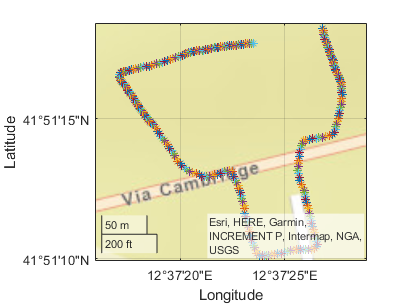

for i = 1:(length(LAT)-1)       % Loop for live plot
   geoplot(LAT(i),LON(i),'-*')
   geobasemap streets           % Rappresentation based on geographic grid
   pause(0.1);     
   hold on;
end 

i = 0;
av_speed = 0;
inst_speed = Position(TIMEposition,"speed" );
inst_speed = table2array(inst_speed);

for i = 1:+1:271
    av_speed = av_speed + inst_speed(i);
end

av_speed = (270 / av_speed) * (1000/60) % Average speed in min/Km

av_speed = 6.4790

steps = round(totaldis/step)           % Steps taken

steps = 1313

kcal = round(steps * 0.0005 * weight)   % Burned calories

kcal = 53